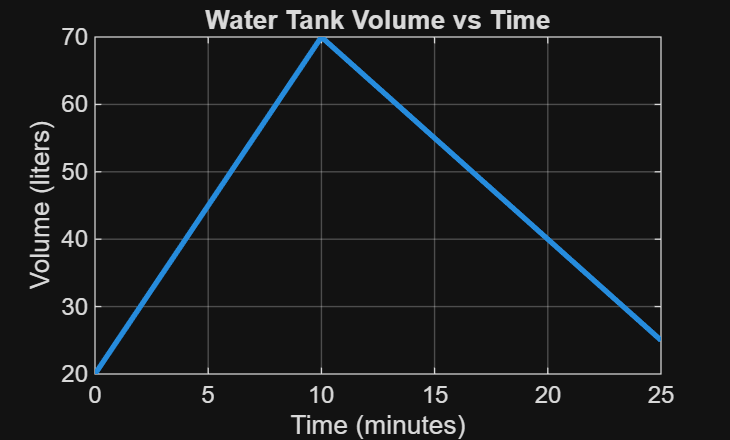

% Zulaikha Khan 
% ES 115 Engineering Computer Applications 
% Module 4 Project: Water Tank Fill-and-Drain 
% Instructor: Lynroy Grant 
% March 28, 2026 
 
clear; clc; close all; 
 
% ---------------------------- 
% Define time values 
t = 0:1:25; 
 
% Initialize volume array 
V = zeros(size(t)); 
 
% ---------------------------- 
% Piecewise model 
 
% Filling phase (0–10 min) 
V(t <= 10) = 5*t(t <= 10) + 20; 
 
% Draining phase (10–25 min) 
V(t > 10) = -3*(t(t > 10) - 10) + 70; 
 
% ---------------------------- 
% Plot volume vs time 
figure; 
plot(t, V, 'LineWidth', 2); 
 
title('Water Tank Volume vs Time'); 
xlabel('Time (minutes)'); 
ylabel('Volume (liters)'); 
grid on; 

 
% ---------------------------- 
% Find when V = 50 liters 
index_50 = find(V == 50); 
 
t_50 = t(index_50); 
 
disp('Time(s) when volume is 50 liters:'); 

Time(s) when volume is 50 liters:


disp(t_50); 

     6



 
% ---------------------------- 
% Create table (at least 12 rows) 
T = table(t', V', 'VariableNames', {'Time_min', 'Volume_L'}); 
disp('Sample table (first 12 rows):'); 

Sample table (first 12 rows):


disp(T(1:12,:)); 

    Time_min    Volume_L
    ________    ________

        0          20   
        1          25   
        2          30   
        3          35   
        4          40   
        5          45   
        6          50   
        7          55   
        8          60   
        9          65   
       10          70   
       11          67   

